TT=2000;
dt = 0.001;
t=0.001:dt:TT*dt;
I_F= zeros (1, TT);
VS = zeros(1, TT);
I =    zeros(1, TT);
FWE = zeros(1, TT);
TED = zeros(1, TT); 
ES = zeros (1, TT);
omega = zeros(1, TT);

Inertia = 137;
N=16;
L_HSX = 20e-3;
R_HSX = 90e-3;
RPM(1) = 1920;

k=0.70584934;
VS(1) = k*RPM(1);

FWE(1) = N*0.5*Inertia*(pi*RPM(1)/30)^2;
CurveFitting;
I_F=fitresult(k);
for i = 1:1:TT
    
    if i == 1
        I(i) = 0
    else
        dI = (VS(i-1) - I(i-1)*R_HSX)*dt/L_HSX;
        I(i) = I(i-1)+ dI;
    end
    
    if i == 1
        TED(i) = I(i)^2*R_HSX;
    else
        TED(i) = TED(i-1)+I(i)^2*R_HSX*dt;
    end
      
    ES(i) = 1/2*(I(i))^2*dt;
    
    NFE(i) = FWE(1) - TED(i) - ES(i);
    
    k_arr(i)=k;
    
    if i == 1
       NFE(i) = FWE(1);
       omega(i) = sqrt(NFE(i)/(N*0.5*Inertia));
    else
        NFE(i) = FWE(1) - TED(i) - ES(i);
        omega(i) = sqrt(NFE(i)/(N*0.5*Inertia));
        RPM(i) = 30*omega(i)/pi;
        
        if i > 745 && i < 850;
            kp=0.00002;
            error = I(740) - I(i);
            k=k+error*kp;
            k_arr(i)=k;
            
                    
        elseif k > 850;
             k_arr(i)=k;
        end
 
        
        VS(i) = RPM(i)*k;
        I_F(i)=fitresult(k);
      
    end
  
    
end

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


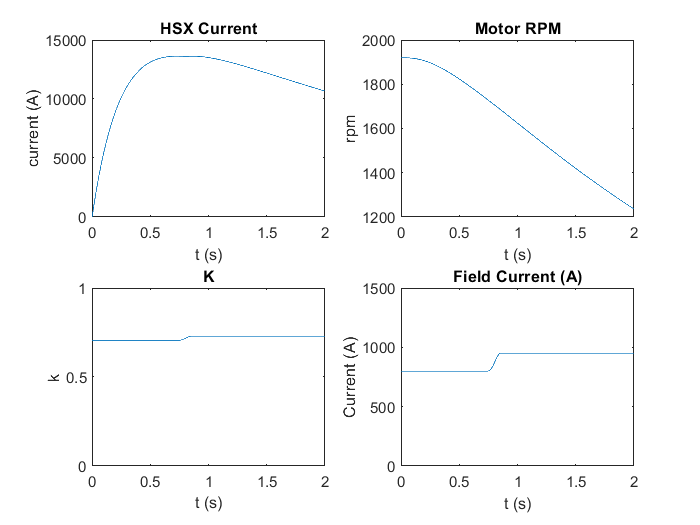


subplot(2,2,1)
plot(t, I)
title('HSX Current')
xlabel('t (s)')
ylabel('current (A)')

subplot(2,2,2)
plot(t, RPM)
title('Motor RPM')
xlabel('t (s)')
ylabel('rpm')

subplot(2,2,3)
plot(t, k_arr)
title('K')
xlabel('t (s)')
ylim([0 1]);
ylabel('k')

subplot(2,2,4)
plot(t, I_F)
title('Field Current (A)')
ylim([0 1500]);
xlabel('t (s)')
ylabel('Current (A)')